# Time-Series Forecasting with MATLAB: Thailand GDP Analysis

**Objective: **Demonstrate MATLAB's Econometric Modeler for economic time-series analysis using Thailand GDP data

**Key Features:** 

- Data Import and Preparation 

- Exploratory Data Analysis 

- Stationarity Testing (Augmented Dickey-Fuller) 

- ACF/PACF Analysis 

- ARIMA Model Specification & Fitting 

- Forecasting with Confidence Intervals

clear; clc; close all;

## Low-code programming with Econometric Modeler

Data: GDP (current US$) in billions - Annual 2000-2023 Source: World Bank DataBank

## 1.Data Access

import Thailand_GDP_Data.csv

% import using live task\

% Import data from text file
GDPDataTT = readtable("D:\Live Demo Matlab\7.DemoKantika2025\Finance\Demo BOT\ForecastingThailand GDP Analysis\Thailand_GDP_Data.csv");

% Display results
GDPDataTT

GDPDataTT = 24×2 table
    Year     GDP  
    ____    ______

    2000    122.68
    2001    126.75
    2002    133.82
    2003    143.51
    2004    162.24
    2005    180.68
    2006    206.59
    2007    235.11
    2008    259.42
    2009    282.72
    2010    308.82
    2011    334.15
    2012    365.97
    2013     398.5
    2014    417.59
    2015    455.21


## 2. Create time table

dates = datetime(Thailand_GDP_Data.Year, 1, 1);
TT = timetable(dates, Thailand_GDP_Data.GDP, 'VariableNames', {'GDP_Billions'});

fprintf('\nFirst 3 Observations:\n');


First 3 Observations:


disp(head(TT, 3));

       dates       GDP_Billions
    ___________    ____________

    01-Jan-2000       122.68   
    01-Jan-2001       126.75   
    01-Jan-2002       133.82   



fprintf('\nLast 3 Observations:\n');


Last 3 Observations:


disp(tail(TT, 3));

       dates       GDP_Billions
    ___________    ____________

    01-Jan-2021       505.98   
    01-Jan-2022       514.23   
    01-Jan-2023       528.17   



## 3.Preprocessing Data

### Log Transformation

%preprocessing data live task
GDP_BillionsLog = log(TT.GDP_Billions);

### Detrend Data

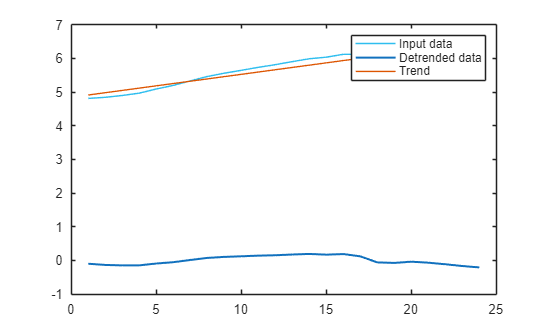

% Remove trend from input data
detrendedData = detrend(GDP_BillionsLog);

% Display results
figure
plot(GDP_BillionsLog,SeriesIndex=6,DisplayName="Input data")
hold on
plot(detrendedData,SeriesIndex=1,LineWidth=1.5,DisplayName="Detrended data")
plot(GDP_BillionsLog-detrendedData,SeriesIndex=2,LineWidth=1, ...
    DisplayName="Trend")
hold off
legend

Input Data : GDP(Log transform) ขึ้นเรื่อย (มี Trend ชัด)   → ไม่ Stationary → ใช้ ARIMA ไม่ได้

Trend : เส้นแนวโน้มเส้นตรง (Linear) บอกว่า "GDP ขึ้นประมาณเท่าไหร่ต่อปี"

Detrended Data : ข้อมูลที่หลัง Trend ออกแล้ว แกว่งรอบ 0 (Up-Down สม่ำเสมอ) → Stationary → ใช้ ARIMA ได้

ตอนนี้เรามี Detrended Data แล้ว

 ขั้นตอนถัดไป: 

1. ใช้ Detrended Data ทำ ARIMA 

2. ทดสอบ Stationarity (ADF Test) ใหม่    → ควรได้ p-value < 0.05 

3. ดู ACF/PACF 

4. สร้างโมเดล ARIMA 5. พยากรณ์

## 4.Perform Data Analysis and Modelling

econometricModeler

#### **Import Data to the modeller**

Import Data to Econometric Modeler

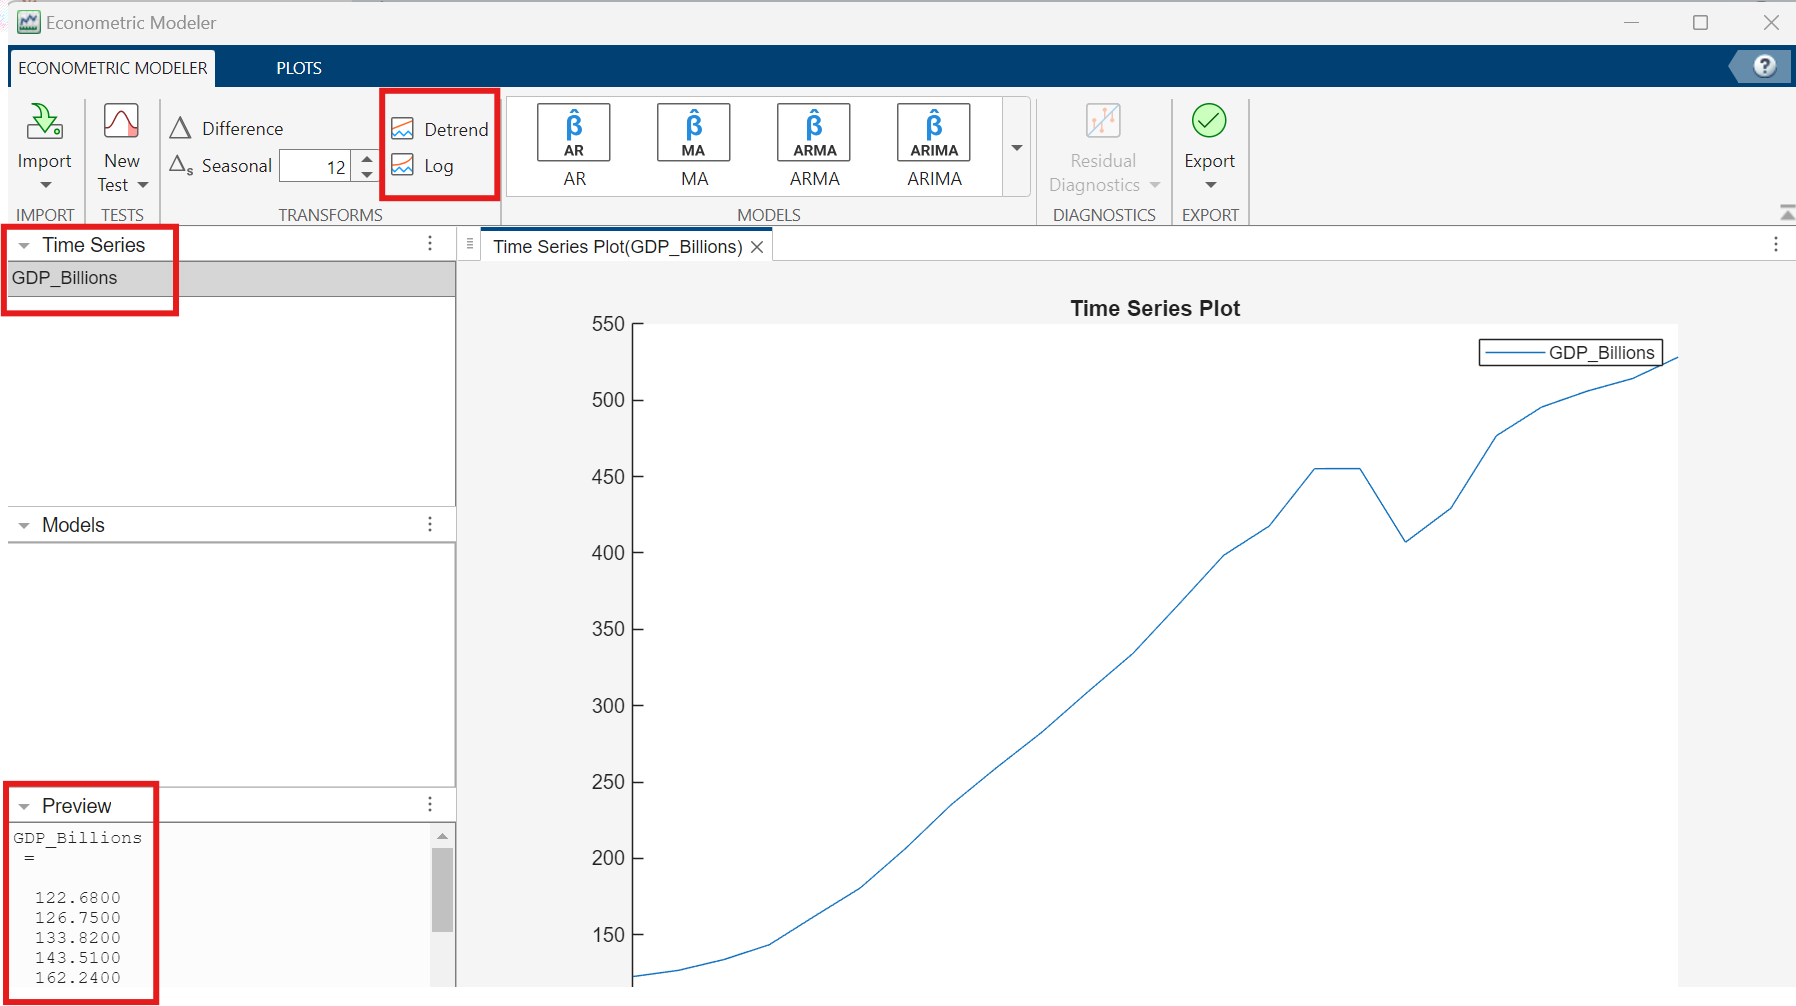

#### Data Transformation

**Step 1. Check for Stationarity.** If non-stationary, then apply differencing/seasonal differencing *(d)*. Finally, you can test again for Stationarity.

The stationarity test results suggest whether you should transform a series to stabilize it, and which transformation is appropriate.

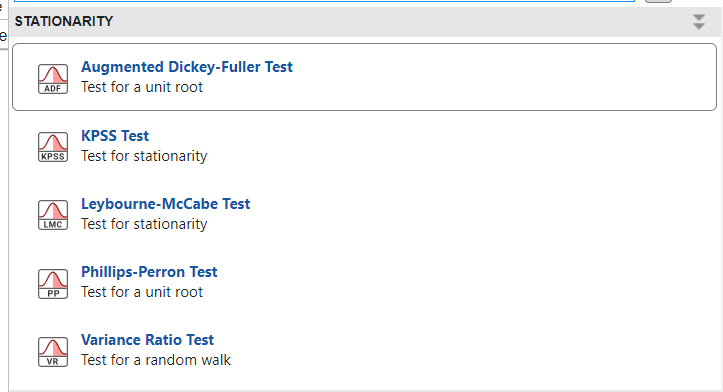

**Setting this value in the APP**

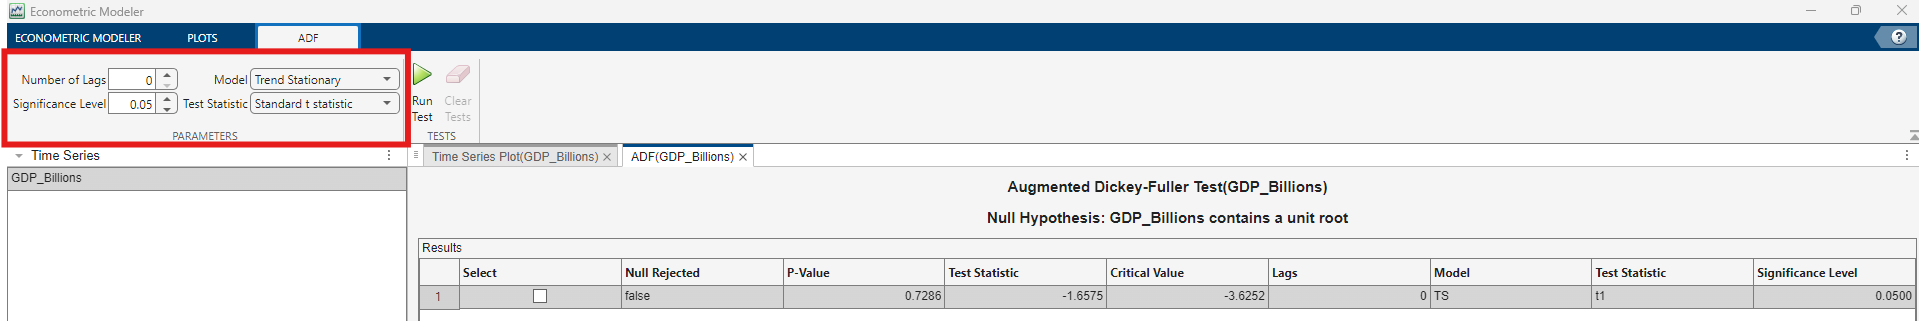

**P-Value (0.7286) > 0.05  FAIL TO REJECT H0   = ข้อมูลยังเป็น NON-STATIONARY   = ต้องแปลงข้อมูล

 p-value < 0.05:    → "Stationary"  → Go to Next Step 2

For example, the** Augmented Dickey-Fuller Test** allows you to test stationarity with the following Hypotheses.

**H0:** Series is non-stationary.

**H1:** Series is stationary.

You can test (with various test statistic) on the following parameters (number of lags, model type). Apply differencing or detrending as needed.

Model Type includes:

    Autoregressive (AR) - test on data if stationary around 0 mean.

    AR with drift - test on data if stationary around nonzero mean.

    Trend Stationary (TS) - test on data if stationary around a linear trend.

**Step 1.1 Difference**

ทำการ **Difference 1 ครั้ง** แล้วทดสอบด้วย **Augmented Dickey-Fuller (ADF) Test**

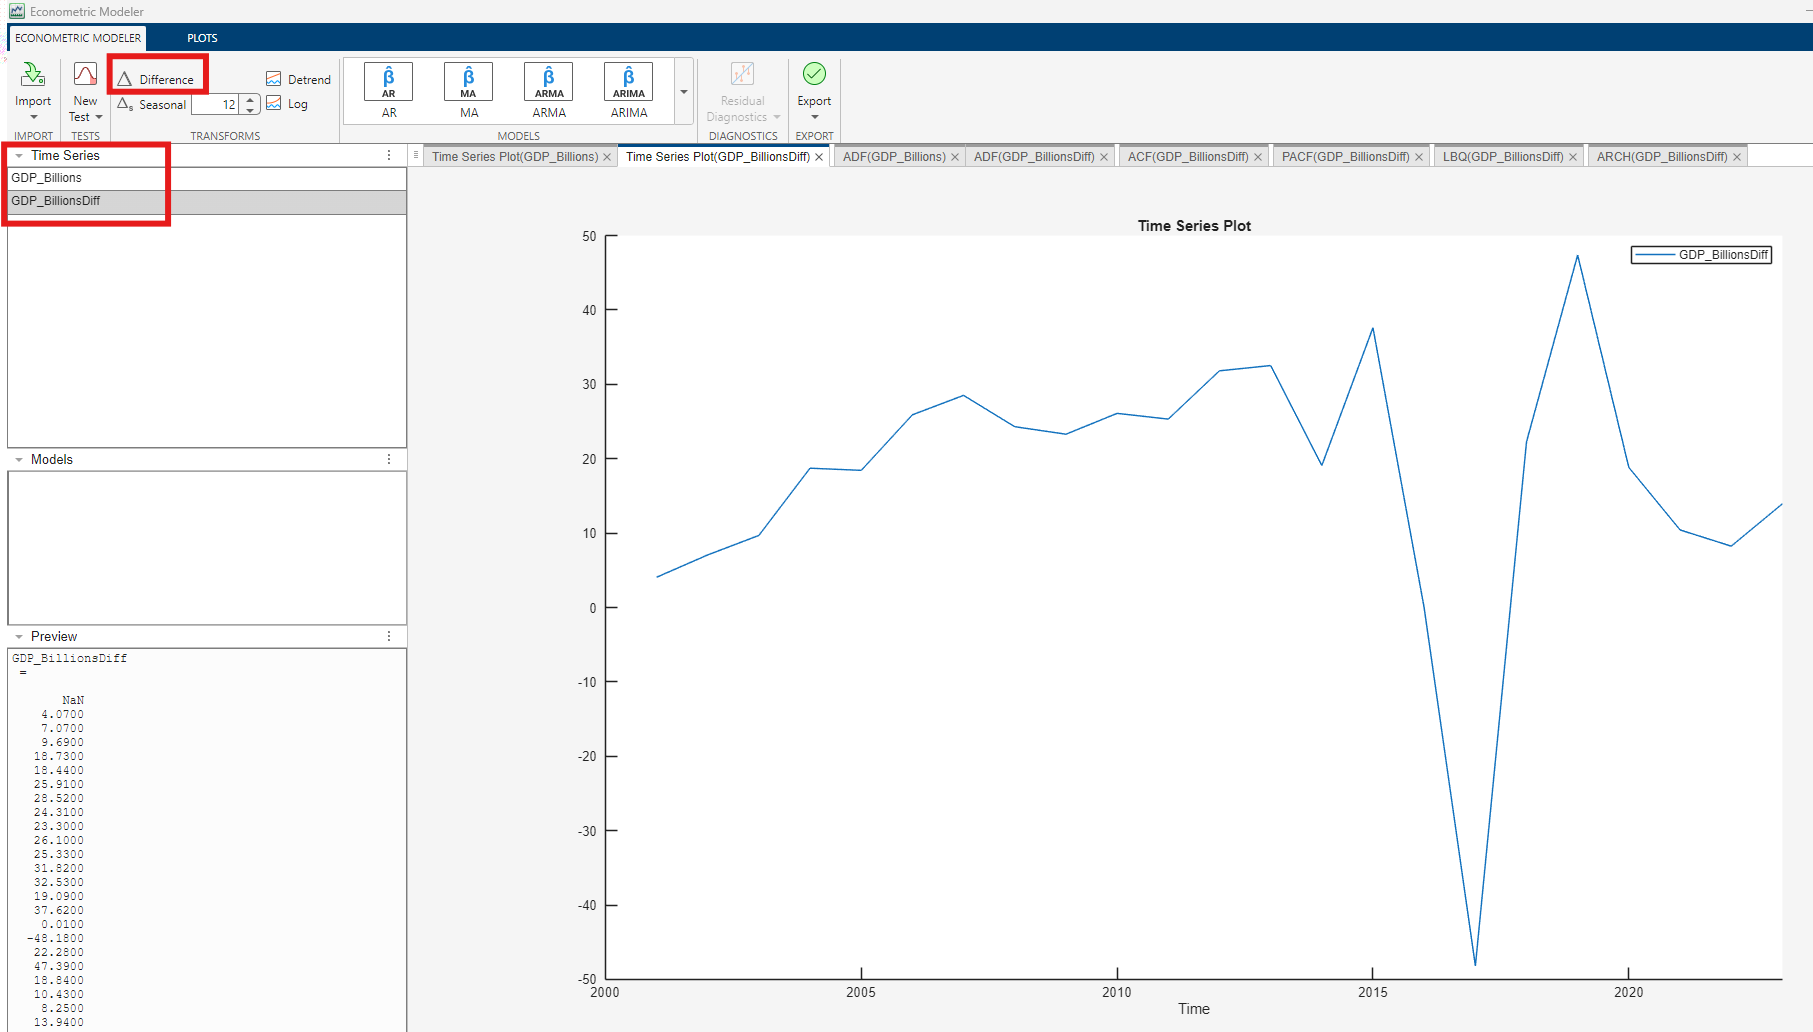

ค่า **p-value = 0.0129 < 0.05 **สรุป: ข้อมูล `GDP_BillionsDiff` ตอนนี้เป็น **Stationary แล้ว**

หมายความว่าไม่มี “trend” เหลือในข้อมูล — พร้อมนำไปสร้างโมเดล ARIMA

**Step 2 ACF/PACF plots for model identification**

Plot ACF and PACF to find the *p *and *q *order of the ARMA model. You can apply differencing/seasonal differencing as needed.

ตอนนี้เราต้องการหาค่าพารามิเตอร์ 2 ตัวคือ

- **p** = จำนวนของ AR terms (จาก PACF)

- **q** = จำนวนของ MA terms (จาก ACF)

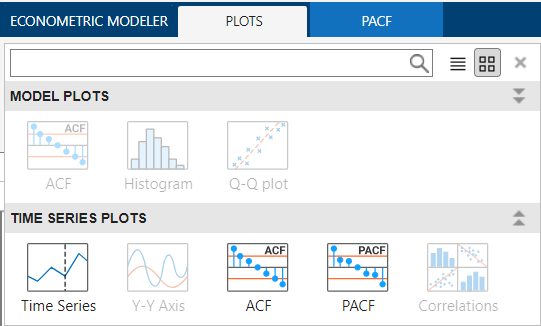

Plot ACF

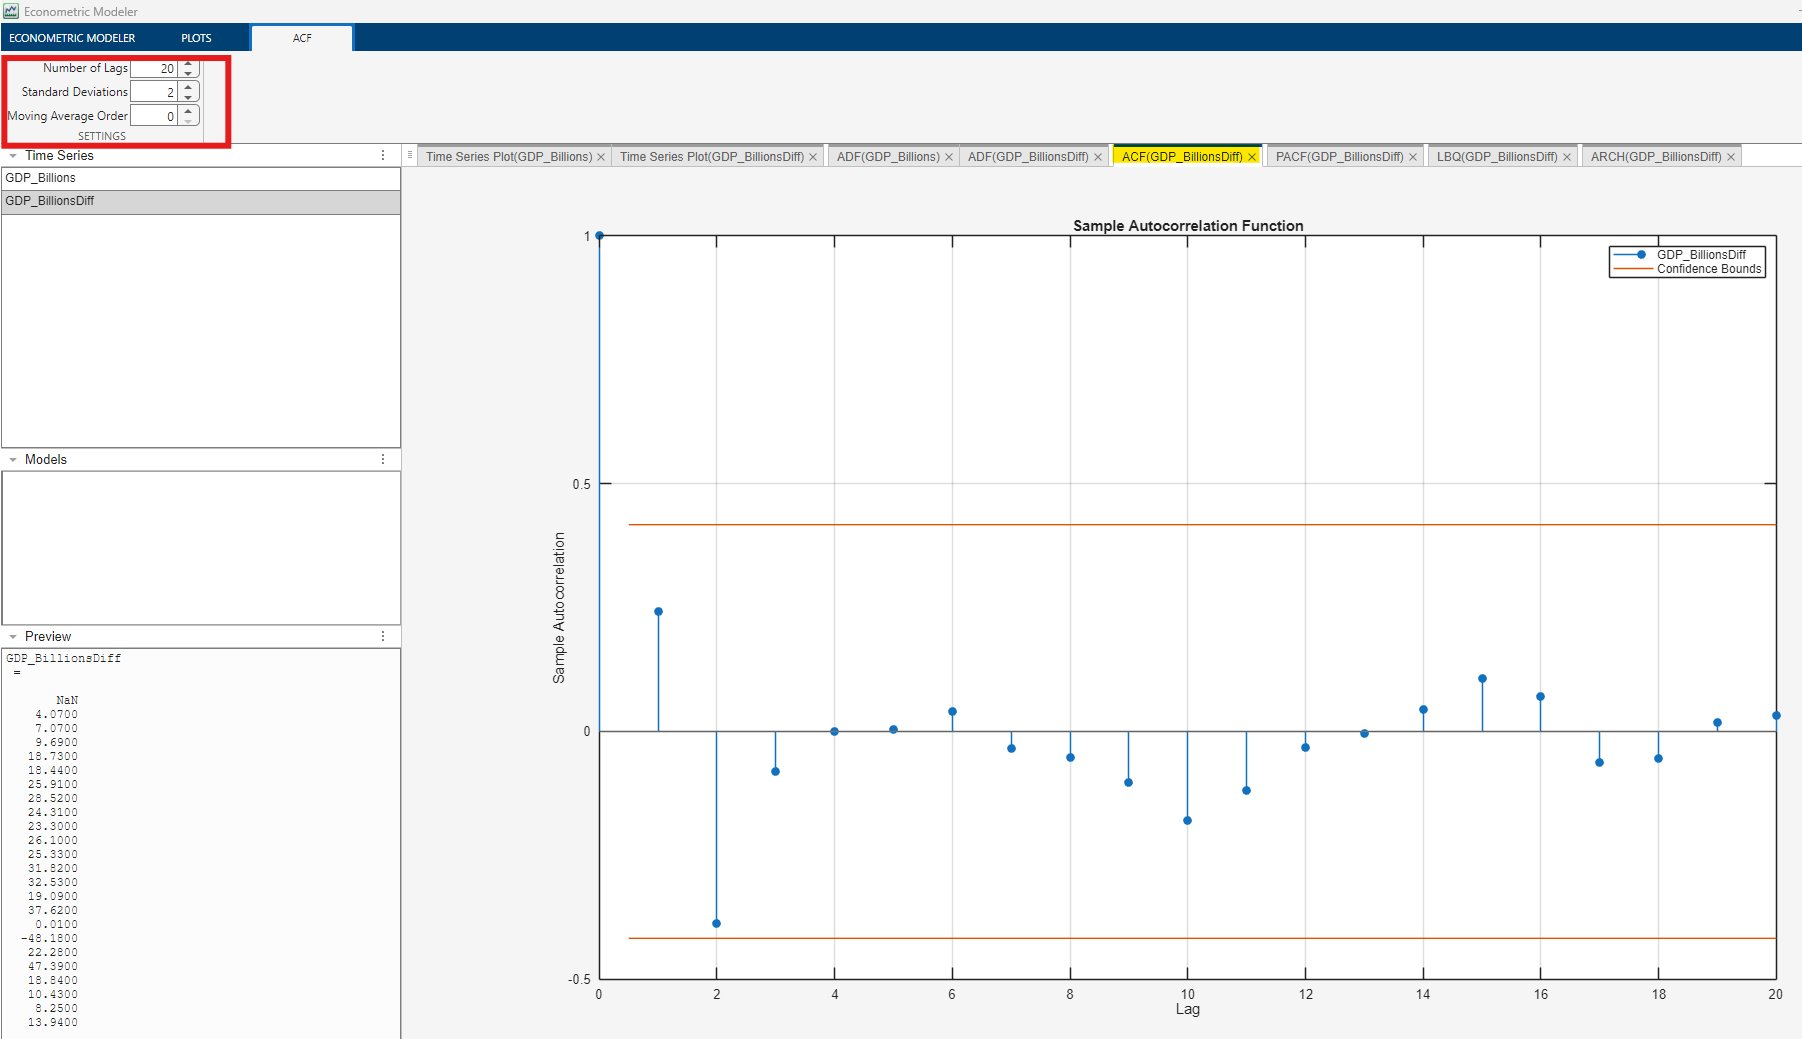

- ไม่มีค่าใดของ lag ที่สูงเกิน “เส้นส้ม” (Confidence Bound)→ หมายความว่า **ไม่มี autocorrelation เหลืออยู่ในข้อมูล**

สรุปว่า “ส่วนของ MA (Moving Average)” น่าจะไม่จำเป็นมาก ดังนั้น **q ≈ 0**

****จุดที่ Lag = 0** มีค่า correlation = 1 เสมอ

เพราะมันคือการเทียบตัวเองกับตัวเอง (ค่าความสัมพันธ์ 100%) ซึ่ง **เป็นเรื่องปกติ ไม่ต้องตีความ**

เราจะเริ่มวิเคราะห์ตั้งแต่ **Lag 1 ขึ้นไป**

Plot PACF

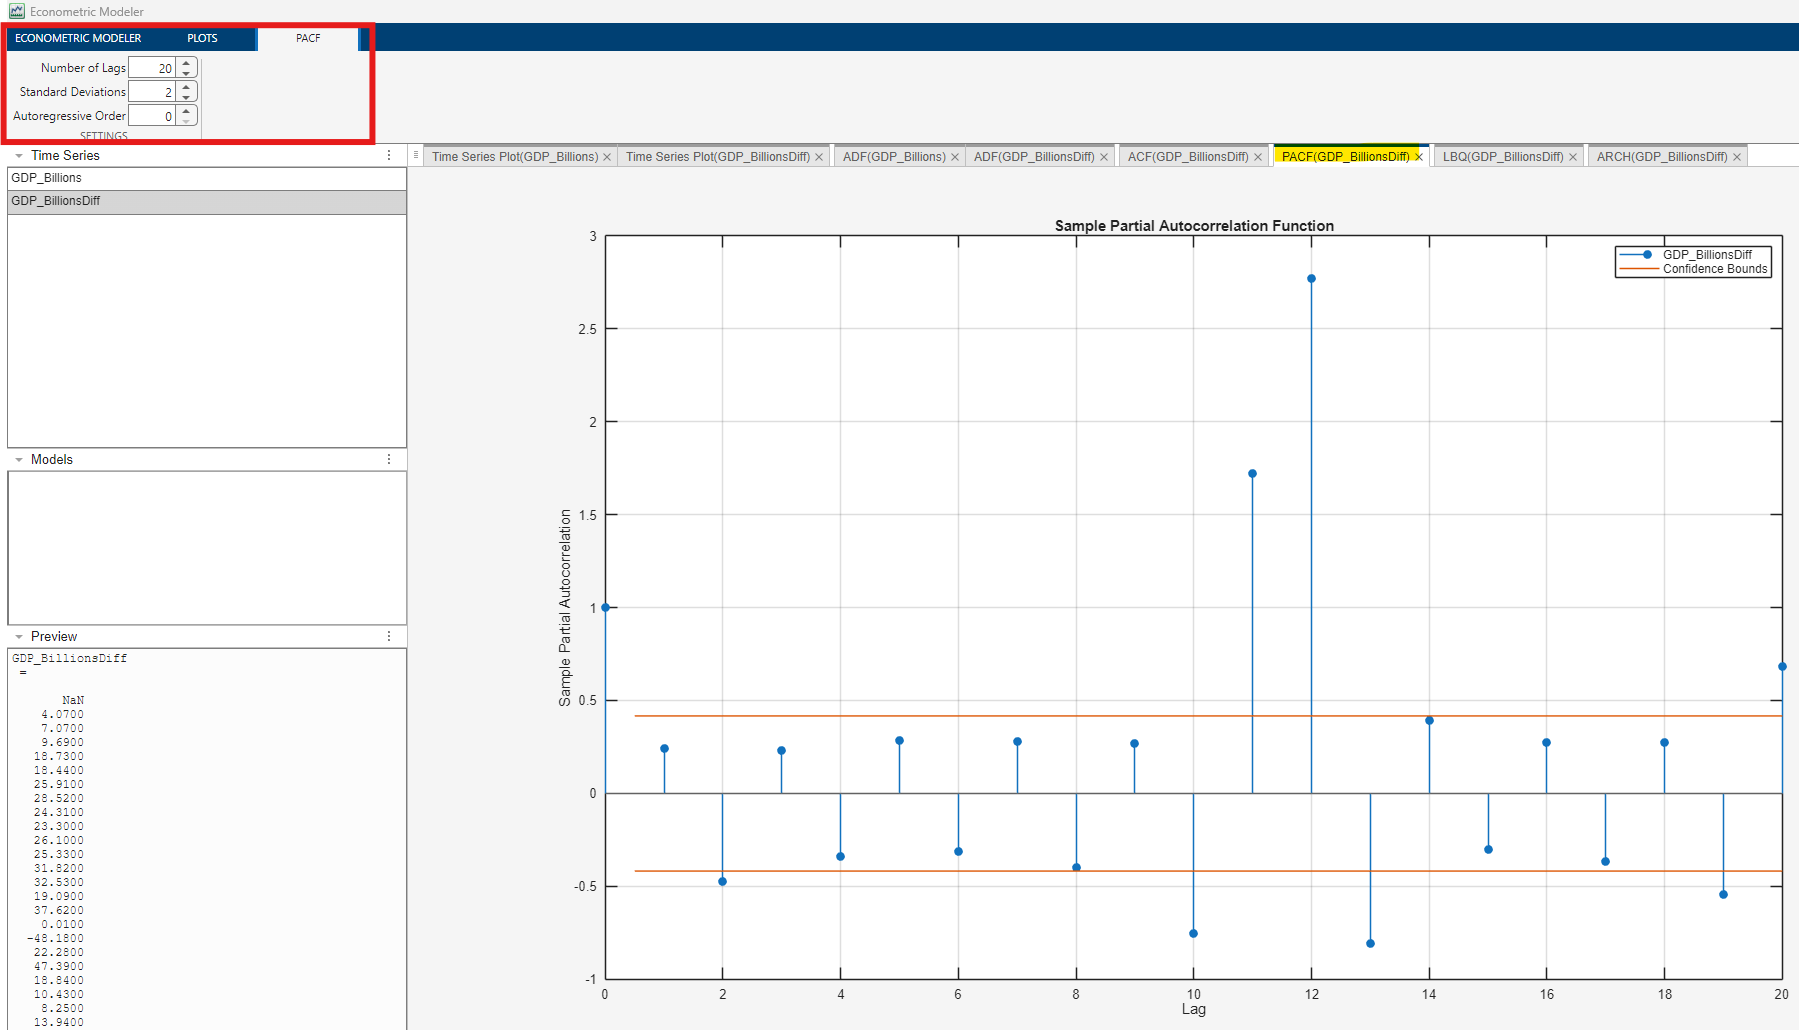

- จุด spike ที่ชัดเจน **อยู่ที่ Lag 10, 11, 12, 13**

- ที่เหลือก่อนหน้า (Lag 1–9) อยู่ในช่วงเส้นส้ม (ไม่ significant)

“ข้อมูลในปัจจุบันของ GDP มีความสัมพันธ์โดยตรงกับค่าในอดีตช่วงประมาณ 10–13 ช่วงเวลาก่อนหน้า”

ดังนั้น ลองสร้างโมเดล ARIMA ที่มี AR term อยู่ในช่วงนี้ เช่น **ARIMA(10,1,0)** หรือ **ARIMA(12,1,0) **แล้วเปรียบเทียบค่า AIC/BIC เพื่อเลือกโมเดลที่ดีที่สุด

**Step 3 **ARIMA parameter estimation (p,d,q)

Based on your ACF and PACF plots, you are ready to create your model. Select the original Time Series and select SARIMA as your model.

#### Selecting your Model

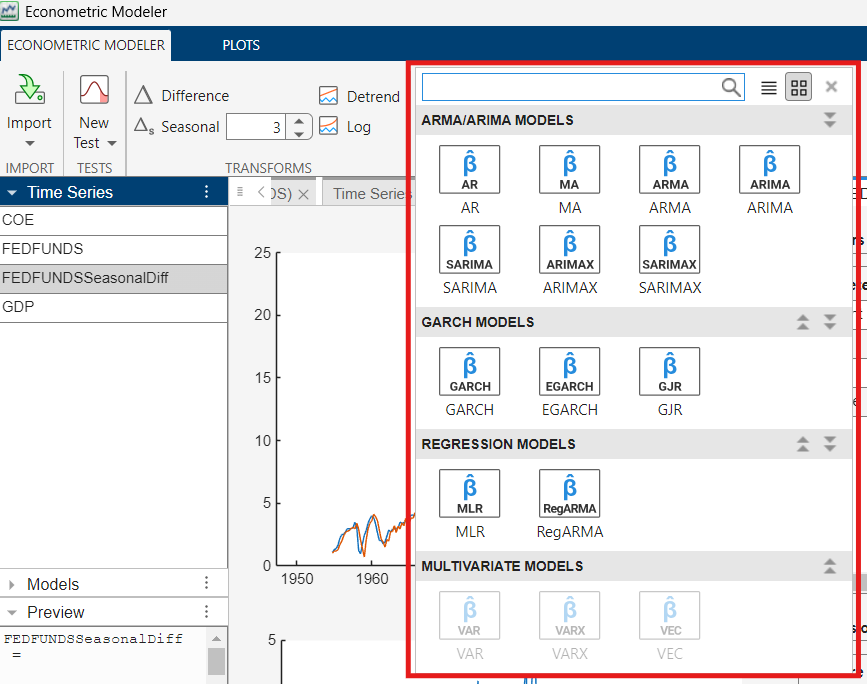

ARIMA *(Autoregressive Integrated Moving Average)* - Model the mean (or level) of a time series by capturing autocorrelation, trends, and seasonality. It assumes errors have constant variance.

GARCH *(Generalized Autoregressive Conditional Hetesocedasticity) *-  Models the *variance* (volatility) of a time series by capturing periods of high and low fluctuations.

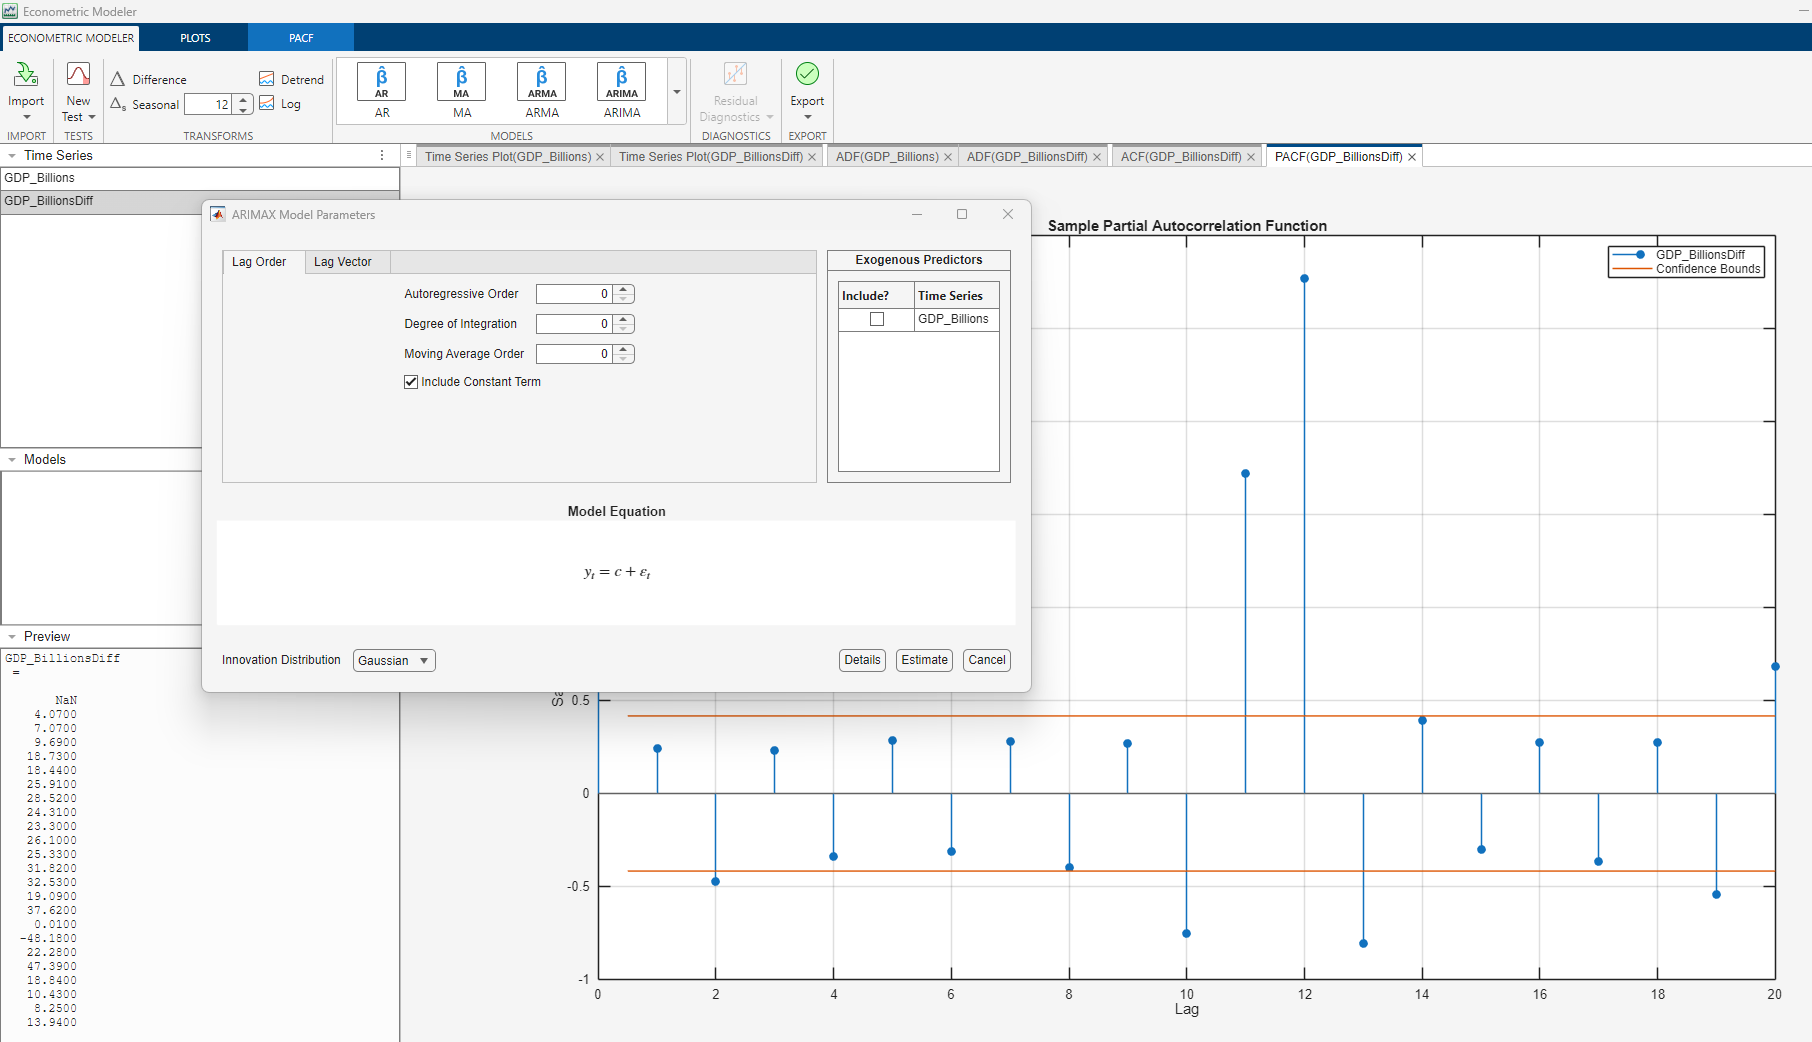

**Analysis Model**

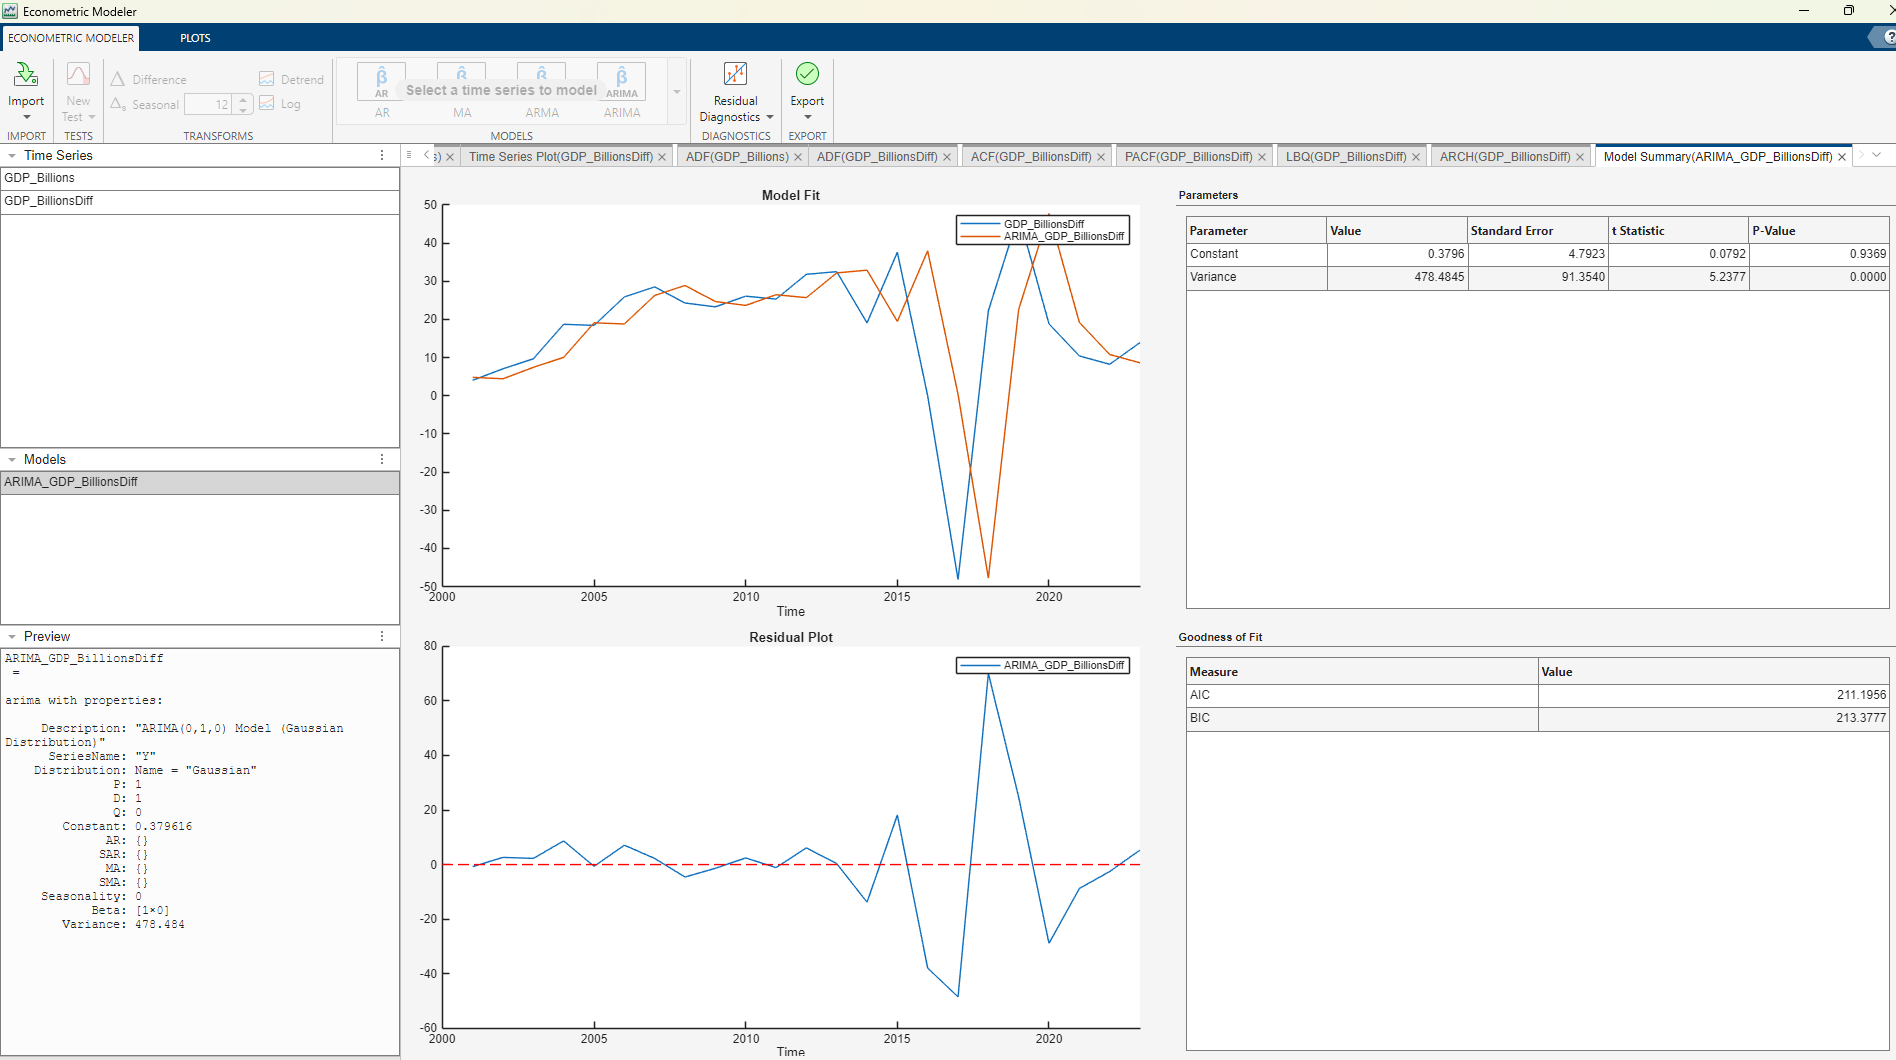

**ประเมินโมเดล ARIMA(0,1,0)** สำหรับข้อมูล `GDP_BillionsDiff` ซึ่งถือเป็น “โมเดลง่ายสุด” หรือที่เรียกว่า **Random Walk Model **“ค่าปัจจุบันของ GDP จะเท่ากับค่าก่อนหน้า + ค่าคงที่เล็กน้อย + ความผันผวนแบบสุ่ม”

**สรุปทางสถิติ:**

โมเดลนี้ไม่มีแนวโน้มชัดเจน (drift ≈ 0)

→ ข้อมูล GDP_diff มีลักษณะเป็น **random fluctuation** หลังการ difference

ลอง “ปรับ ARIMA ด้วย Lag Vector” ARIMA(10,1,0) 

- **ARIMA(10,1,0)**

- **Lag Vector:** [10] → ใช้เฉพาะค่า GDP ที่ย้อนหลัง 10 ช่วงเวลา

- **d = 1** (Difference 1 ครั้ง เพื่อให้ข้อมูล Stationary)

- **q = 0** (ไม่มี MA component)

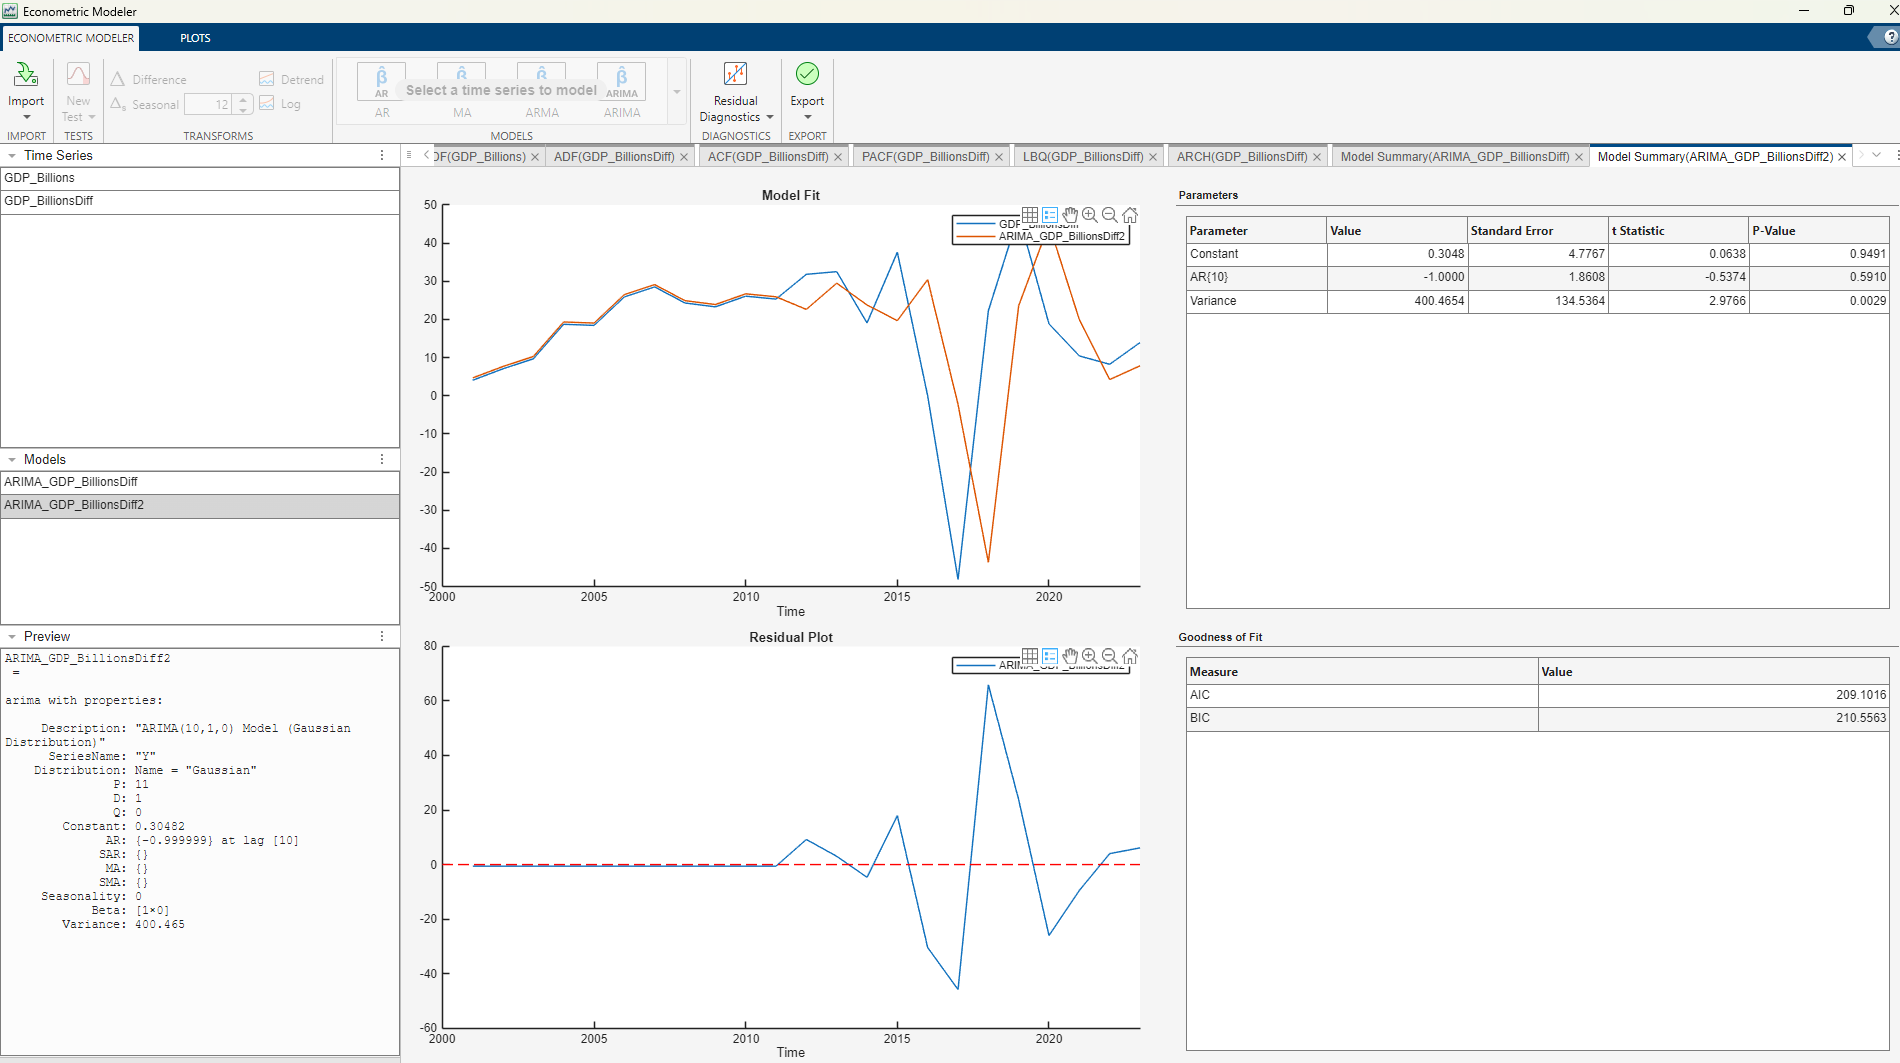

**Goodness of Fit (AIC/BIC)**

SARIMA Model Parameters

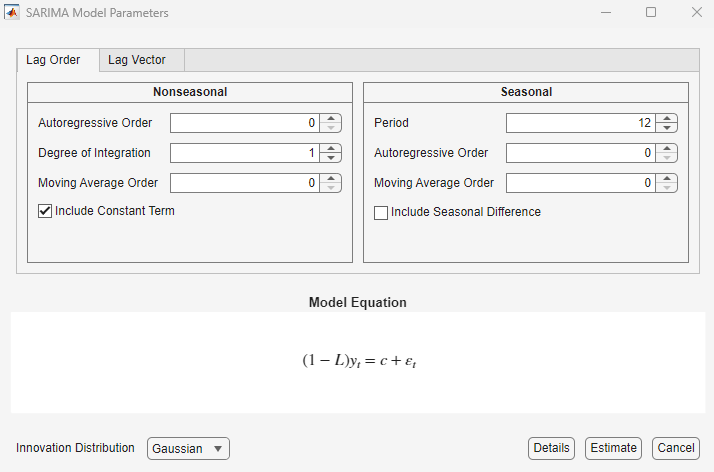

## 5.Model Deployment

There are various options to deploy your model to MATLAB. We can deploy the model we created as

- Function and Live Function

- Report and Documentation

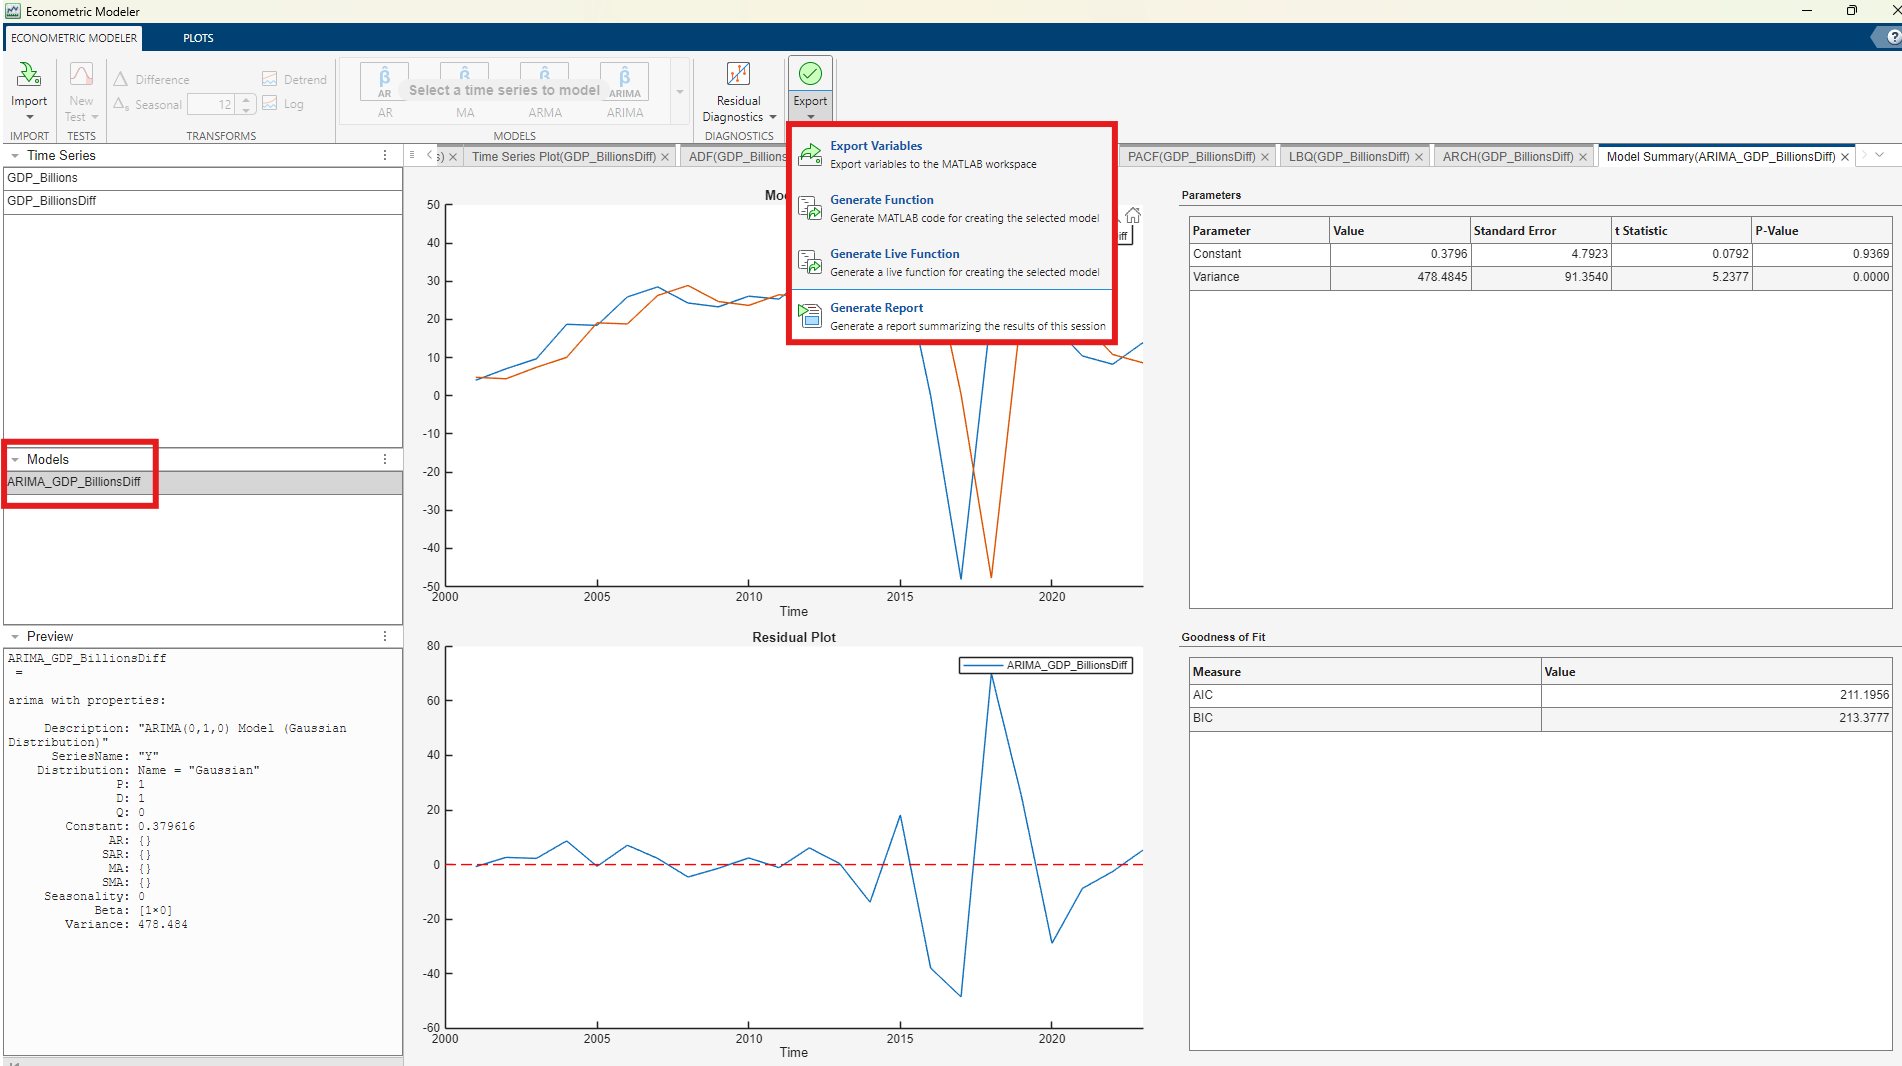

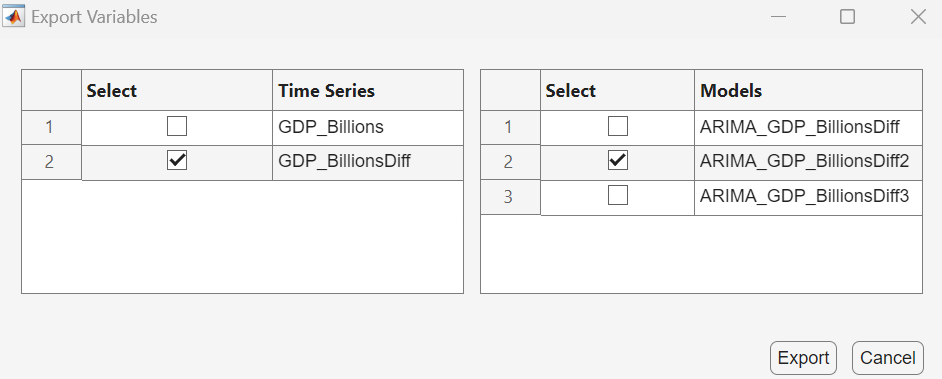

## 6.Estimate Data

EstMdl = modelTimeSeries(TT);
% [E0, V] = infer(EstMdl, detrendedlogData);
% detrendedlogHat = detrendedlogData - E0;

## 7.Forecast Data

mdlDiff   = ARIMA_GDP_BillionsDiff2;     % ARIMA model fitted on the differenced series
yDiff     = GDP_BillionsDiff(:);         % Differenced time series (as a column vector)
yLevel    = GDP_Billions(:);             % Original time series in actual (level) values
years     = Thailand_GDP_Data.Year(:);   % Year values (numeric)
steps     = 6;                           % Number of forecast periods (years ahead)

alpha     = 0.05;                        % Significance level for 95% confidence interval
z         = norminv(1-alpha/2);

% Forecast diff scale
[Yf_diff, YMSE] = forecast(mdlDiff, steps, 'Y0', yDiff);
se      = sqrt(YMSE);
CI_diff = [Yf_diff - z*se,  Yf_diff + z*se];

### 7.1)Convert to the original GDP level

% convert original scale
lastLevel   = yLevel(end);
Yf_level    = lastLevel + cumsum(Yf_diff);
CI_low_lvl  = lastLevel + cumsum(CI_diff(:,1));
CI_high_lvl = lastLevel + cumsum(CI_diff(:,2));

### 7.2)Make dates & plots

% Generate future years (numeric axis)
fcstYears = (years(end)+1 : years(end)+steps)';

% Simple Plot 
figure; hold on; box on;
plot(years, yLevel, 'b-', 'LineWidth', 1.8);                  % Plot actual historical data
plot(fcstYears, Yf_level, 'r*-', 'LineWidth', 1.8);           % Plot forecasted points/line์

% Plot 95% confidence interval (shaded area)
xpatch = [fcstYears; flipud(fcstYears)];
ypatch = [CI_low_lvl; flipud(CI_high_lvl)];
fill(xpatch, ypatch, [0.8 0.8 0.8], 'EdgeColor','none', 'FaceAlpha',0.25);

% Highlight the forecast period (light gray background)
yl = ylim;
patch([fcstYears(1) fcstYears(end) fcstYears(end) fcstYears(1)], ...
      [yl(1) yl(1) yl(2) yl(2)], [0.9 0.9 0.95], ...
      'FaceAlpha',0.2, 'EdgeColor','none');
uistack(findobj(gca,'Type','line'),'top');  % Bring lines to the top of the shaded area

legend('Observed','Forecast','95% CI','Forecast period','Location','eastoutside');
xlabel('Year'); ylabel('GDP (Billions)');
title('Thailand GDP Forecast');
axis tight; hold off;

### 7.3)Write Table Save as  .xlsx

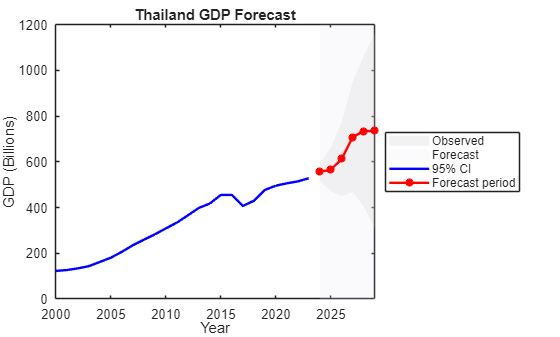

    Year    Forecast    Lower_95CI    Upper_95CI
    ____    ________    __________    __________

    2024     555.85       516.63        595.08  
    2025     565.31       470.62           660  
    2026     612.69       450.06        775.31  
    2027     708.56       467.49        949.63  
    2028     734.27        405.5          1063  
    2029     735.18       310.33          1160  



FcstTbl = table(fcstYears, Yf_level, CI_low_lvl, CI_high_lvl, ...
   'VariableNames',{'Year','Forecast','Lower_95CI','Upper_95CI'});
disp(FcstTbl);
writetable(FcstTbl,'GDP_Forecast_ARIMA.xlsx');

## Key Takeaways

- Many interactive and easy to use apps that can help explore,iterate and automate workflows.

- Flexibility and options to choose networks and optimizations based on data and requirements.

- Offers and end-to-end workfow from data preparation to deployment.